clc;
clear;
close all;

% Define Transfer Function
num = [1];
den = [1 3 2];   % G(s) = 1/(s^2 + 3s + 2)

sys = tf(num,den);

disp('Transfer Function of the System:')

Transfer Function of the System:


sys


sys =
 
        1
  -------------
  s^2 + 3 s + 2
 
Continuous-time transfer function.


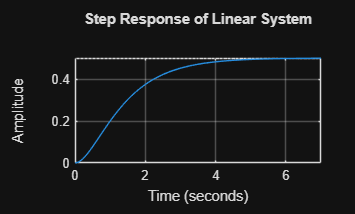


% Time vector
t = 0:0.01:10;

% Step Response
figure;
step(sys);
grid on;
title('Step Response of Linear System');

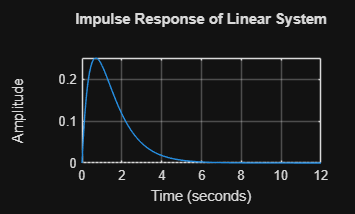


% Impulse Response
figure;
impulse(sys);
grid on;
title('Impulse Response of Linear System');

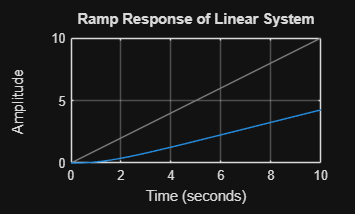


% Ramp Input Response
u = t;    % ramp input
figure;
lsim(sys,u,t);
grid on;
title('Ramp Response of Linear System');

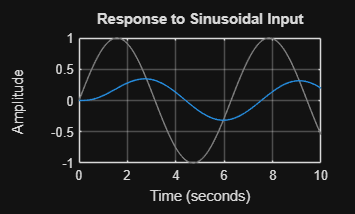


% Sinusoidal Input Response
u2 = sin(t);
figure;
lsim(sys,u2,t);
grid on;
title('Response to Sinusoidal Input');